# Generate our Bell Parameter off the correlations:

## Lists:

phi = 0:pi/180:pi;
E_list = phi;

## Parameters:

$\lambda$ = L - mode occupancy.  

$\phi$ - phase of interferometer.  

$T_{max}$ - maximum number of generated particle

cycles = C - number of simulated tests used to perform correlation.

QE = R - retention rate / quantum efficiency.

dark_rate = D - fraction of tests which return a non-experimental count.

$\sigma$ = B - decay width of gaussian blur in detection uncertainty.

R - radius of $He_4$ halos.

phys - Quantum ('Q') or Classical ('C') physics to be used.

$Y_{\text{bias}}$ - with a classical beam splitter, the R.H.S. bias towards Y (up)

$X_{\text{bias}}$ -         "             "                      , the L.H.S. bias towards X (up)

lambda = 0.1;
% phi =   ;
Tmax = 10;
cycles = 2E5;
QE = 8;
dark_rate = 1E-6;
sigma = 0.30;
R = 1;
phys = 'Q';

## Evaluation for each phase:

for p = 1:length(phi)
    [gYW,gXZ,gYZ,gXW] = correlators(lambda,phi(p),Tmax,cycles,QE,dark_rate,sigma,R,phys,0,0);
    E_list(p) = (gYW + gXZ - gYZ - gXW)/(gYW + gXZ + gYZ + gXW);
    percent = 100*p/length(phi)
end

percent = 0.5525

percent = 1.1050

percent = 1.6575

percent = 2.2099

percent = 2.7624

percent = 3.3149

percent = 3.8674

percent = 4.4199

percent = 4.9724

percent = 5.5249

percent = 6.0773

percent = 6.6298

percent = 7.1823

percent = 7.7348

percent = 8.2873

percent = 8.8398

percent = 9.3923

percent = 9.9448

percent = 10.4972

percent = 11.0497

percent = 11.6022

percent = 12.1547

percent = 12.7072

percent = 13.2597

percent = 13.8122

percent = 14.3646

percent = 14.9171

percent = 15.4696

percent = 16.0221

percent = 16.5746

percent = 17.1271

percent = 17.6796

percent = 18.2320

percent = 18.7845

percent = 19.3370

percent = 19.8895

percent = 20.4420

percent = 20.9945

percent = 21.5470

percent = 22.0994

percent = 22.6519

percent = 23.2044

percent = 23.7569

percent = 24.3094

percent = 24.8619

percent = 25.4144

percent = 25.9669

percent = 26.5193

percent = 27.0718

percent = 27.6243

percent = 28.1768

percent = 28.7293

percent = 29.2818

percent = 29.8343

percent = 30.3867

percent = 30.9392

percent = 31.4917

percent = 32.0442

percent = 32.5967

percent = 33.1492

percent = 33.7017

percent = 34.2541

percent = 34.8066

percent = 35.3591

percent = 35.9116

percent = 36.4641

percent = 37.0166

percent = 37.5691

percent = 38.1215

percent = 38.6740

percent = 39.2265

percent = 39.7790

percent = 40.3315

percent = 40.8840

percent = 41.4365

percent = 41.9890

percent = 42.5414

percent = 43.0939

percent = 43.6464

percent = 44.1989

percent = 44.7514

percent = 45.3039

percent = 45.8564

percent = 46.4088

percent = 46.9613

percent = 47.5138

percent = 48.0663

percent = 48.6188

percent = 49.1713

percent = 49.7238

percent = 50.2762

percent = 50.8287

percent = 51.3812

percent = 51.9337

percent = 52.4862

percent = 53.0387

percent = 53.5912

percent = 54.1436

percent = 54.6961

percent = 55.2486

percent = 55.8011

percent = 56.3536

percent = 56.9061

percent = 57.4586

percent = 58.0110

percent = 58.5635

percent = 59.1160

percent = 59.6685

percent = 60.2210

percent = 60.7735

percent = 61.3260

percent = 61.8785

percent = 62.4309

percent = 62.9834

percent = 63.5359

percent = 64.0884

percent = 64.6409

percent = 65.1934

percent = 65.7459

percent = 66.2983

percent = 66.8508

percent = 67.4033

percent = 67.9558

percent = 68.5083

percent = 69.0608

percent = 69.6133

percent = 70.1657

percent = 70.7182

percent = 71.2707

percent = 71.8232

percent = 72.3757

percent = 72.9282

percent = 73.4807

percent = 74.0331

percent = 74.5856

percent = 75.1381

percent = 75.6906

percent = 76.2431

percent = 76.7956

percent = 77.3481

percent = 77.9006

percent = 78.4530

percent = 79.0055

percent = 79.5580

percent = 80.1105

percent = 80.6630

percent = 81.2155

percent = 81.7680

percent = 82.3204

percent = 82.8729

percent = 83.4254

percent = 83.9779

percent = 84.5304

percent = 85.0829

percent = 85.6354

percent = 86.1878

percent = 86.7403

percent = 87.2928

percent = 87.8453

percent = 88.3978

percent = 88.9503

percent = 89.5028

percent = 90.0552

percent = 90.6077

percent = 91.1602

percent = 91.7127

percent = 92.2652

percent = 92.8177

percent = 93.3702

percent = 93.9227

percent = 94.4751

percent = 95.0276

percent = 95.5801

percent = 96.1326

percent = 96.6851

percent = 97.2376

percent = 97.7901

percent = 98.3425

percent = 98.8950

percent = 99.4475

percent = 100

## Generate Plot / Image:

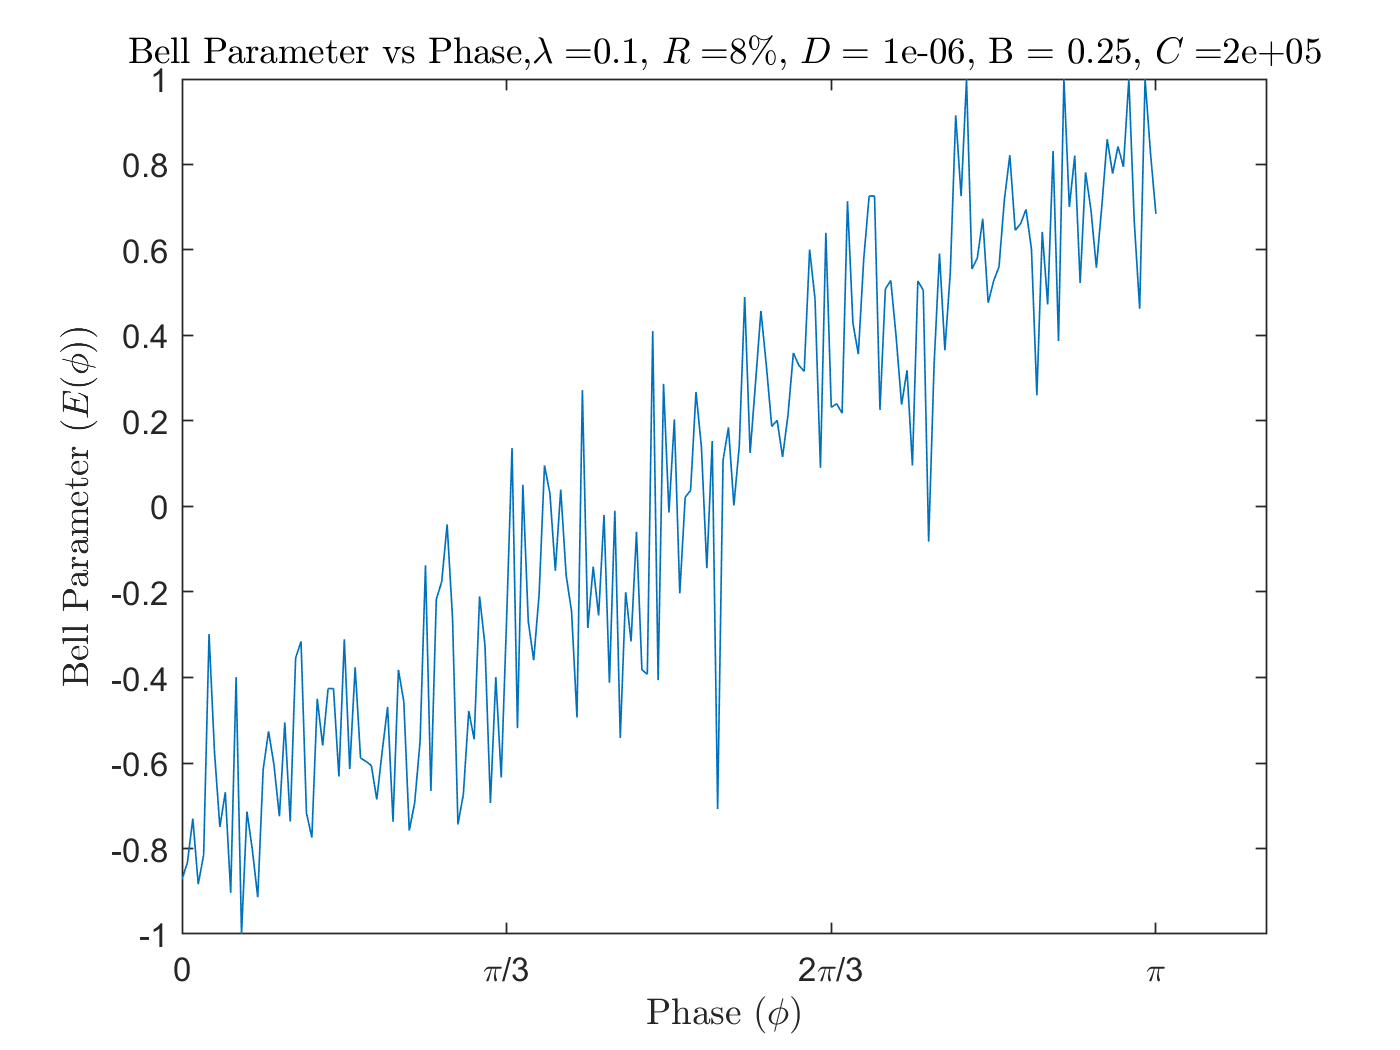

plot(phi,E_list)
xticks([0,pi/3,2*pi/3,pi,4*pi/3,5*pi/3,2*pi])
xticklabels(["0","\pi/3","2\pi/3","\pi","4\pi/3","5\pi/3","2\pi"])
xlabel("Phase ($\phi$)","Interpreter",'latex')
ylabel("Bell Parameter ($E(\phi)$)","Interpreter","latex")
title("Bell Parameter vs Phase,$\lambda = $" + string(lambda) + ", $R =$" + string(QE)+"\%, $D = $" + " "+num2str(dark_rate, '%.0e')+", B = "+string(sigma)+", $C = $"+num2str(cycles,'%.0e'),"Interpreter","latex")

## Write to File:

A = [phi; E_list];
name = erase('R'+string(QE)+'_D'+num2str(dark_rate,'%.0e')+'_B'+string(sigma)+'_C'+num2str(cycles,'%.0e')+'_L'+string(lambda),'.');
data = fopen(name+'.txt','w');
fprintf(data,'%6s %12s\n','\phi','E(\phi)');
fprintf(data,'%6.4f %12.8f\n',A);
fclose(data);